% Connect to sensor and run this

% Uncomment following 3 lines for sensor input
ElikoReconnect();


#############################################################################
#                                                                           #
#   QUADRA(TM) Impedance Data Acquisition Toolbox v1.0 for 64-bit Matlab    #
#   Picometer series devices                                                #
#   (C) Copyright Eliko OÜ 2004 - 2016                                      #
#                                                                           #
#############################################################################

	Picometer device USB connection initialized...
	Device[0] S/N:PM2003013
	HW:v1.02 SW:v1.3 CRC:0AF8 BATTERY:4170mV ST:0 ERR:0000



output = ElikoSample();
PicometerControl('Disconnect');

	Picometer device USB connection closed...


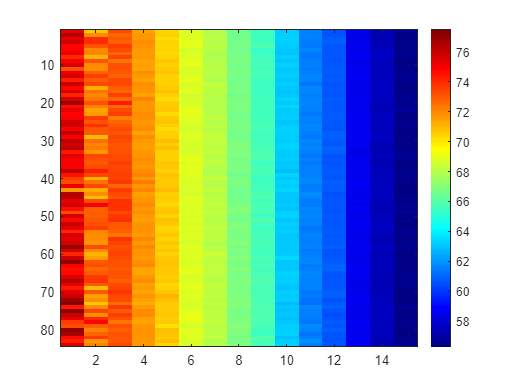


% real1 = real(output(:,1));
% imag1 = imag(output(:,1));
% 
% plot(real1,imag1,'g*');

% Remove the first 15 rows and keep the rest
sliced_matrix = output(16:end, :);

% Compute the magnitudes of each number in the matrix
magnitude_matrix = abs(sliced_matrix);

% Plot the magnitude matrix as image or heatmap
imagesc(magnitude_matrix);
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference

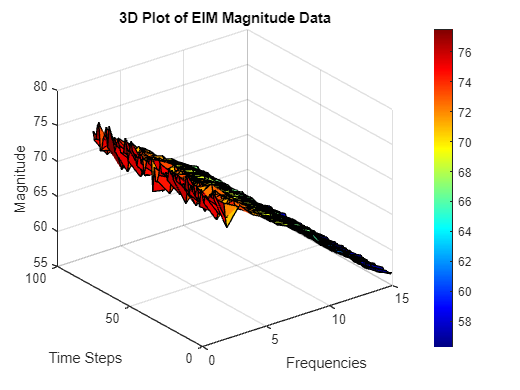


% Assuming magnitude_matrix contains your magnitude data
figure;
surf(magnitude_matrix);

% Customize the plot appearance
title('3D Plot of EIM Magnitude Data');
xlabel('Frequencies');
ylabel('Time Steps');
zlabel('Magnitude');
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference


% Set percentage threshold to identify noise (above threshold is noise)
percentage_threshold = 80;

% Initialize arrays to store thresholds and signal masks for each frequency
num_frequencies = size(magnitude_matrix, 2)  % Assuming magnitude_matrix is Mx15

num_frequencies = 15

thresholds = zeros(1, num_frequencies)

thresholds =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


signal_masks = cell(1, num_frequencies)

signal_masks = 1×15 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


for i = 1:num_frequencies
    % Calculate the maximum magnitude for the current frequency
    max_magnitude = max(magnitude_matrix(:, i));

    % Calculate the threshold value as a percentage of the maximum magnitude
    threshold = (percentage_threshold / 100) * max_magnitude;

    % Create a binary mask where 1 represents signal and 0 represents noise
    signal_mask = magnitude_matrix(:, i) >= threshold;

    % Store the threshold and signal mask for the current frequency
    thresholds(i) = threshold;
    signal_masks{i} = signal_mask;
end

thresholds

thresholds =    62.0118   60.0018   59.3940   57.7756   56.8985   55.2760   54.7243   53.6656   52.8358   50.7352   49.5026   48.7930   47.0072   46.2201   45.4423


signal_masks

signal_masks = 1×15 cell array
    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}    {84×1 logical}


% Apply the masks to the magnitude matrix for each frequency
signal_data = zeros(84,15);
noise_data = zeros(84,15);

for i=1:num_frequencies
    noise_data(:,i) = magnitude_matrix(:,i)-thresholds(i);
    signal_data(:,i) = magnitude_matrix(:,i)-noise_data(:,i);
end 
% signal_data = magnitude_matrix .* cat(2, signal_masks{:});  % Signal components
% noise_data = magnitude_matrix - signal_data;  % Noise components

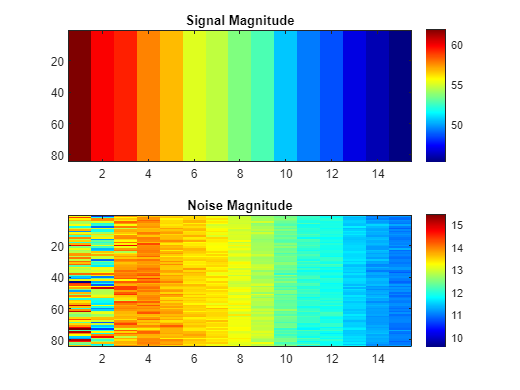

% % Calculate the maximum magnitude value in your data
% max_magnitude = max(magnitude_matrix(:));
% 
% % Calculate threshold
% threshold = (percentage_threshold / 100) * max_magnitude;
% 
% signal_mask = magnitude_matrix >= threshold;
% 
% signal_data = magnitude_matrix .* signal_mask;  % Apply the mask to your complex data
% noise_data = magnitude_matrix .* ~signal_mask;   % Apply the inverse mask for noise

% Visualize the signal and noise separately
figure;
subplot(2, 1, 1);
imagesc(abs(signal_data));
title('Signal Magnitude');
colormap('jet');
colorbar;
subplot(2, 1, 2);
imagesc(abs(noise_data));
title('Noise Magnitude');
colormap('jet');
colorbar;

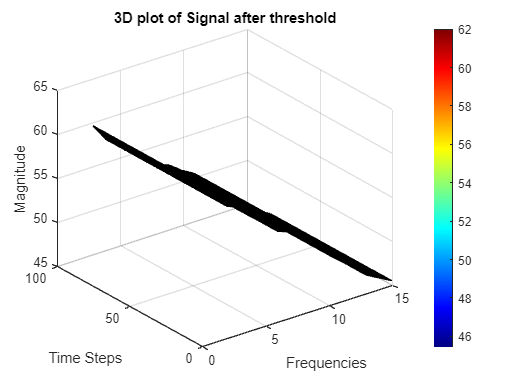



% 3D plot of Signal after threshold
figure;
surf(signal_data);

% Customize the plot appearance
title('3D plot of Signal after threshold');
xlabel('Frequencies');
ylabel('Time Steps');
zlabel('Magnitude');
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference

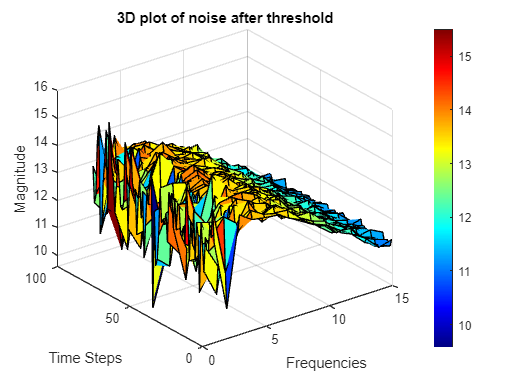


% 3D plot of noise after threshold
figure;
surf(noise_data);

% Customize the plot appearance
title('3D plot of noise after threshold');
xlabel('Frequencies');
ylabel('Time Steps');
zlabel('Magnitude');
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference

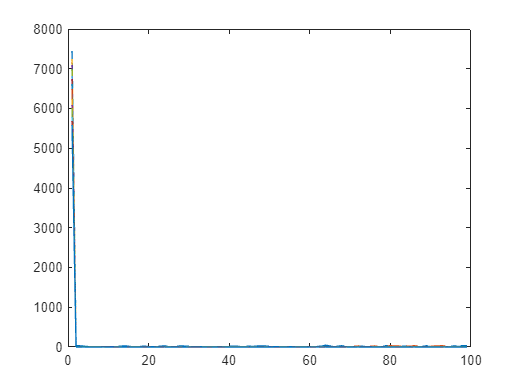

frequencyAnalysis = fft(output);
plot(abs(frequencyAnalysis))

title('FFT of output');
xlabel('Frequency');
ylabel('Magnitude');

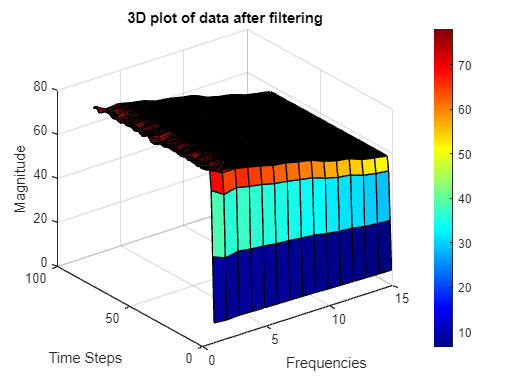

% filterDesigner
x = magnitude_matrix;
Y = filter(Hd, x);
t = 1:length(x);

% plot(t,x,'--',t,Y,'-');
% legend('Original Data','Filtered Data');

% 3D plot of noise after threshold
figure;
surf(Y);

% Customize the plot appearance
title('3D plot of data after filtering');
xlabel('Frequencies');
ylabel('Time Steps');
zlabel('Magnitude');
colormap('jet');  % Use a colormap for better visualization
colorbar;  % Add a colorbar to the plot for magnitude reference